# staticな学習データをGPR

テストデータとも比較して，精度も確認する．

シンプルに解いて，オイラーの回転運動方程式を解いてlight curveを計算して，比較する．

csvの中身：

- xTrain: [q, satPos, obsPos, sunPos]

- yTrain: [mApp]

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/')));
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(strcat(curdir, '/../../gpryui/'));

tStart = tic;

### input values directly

predictionStep = 1; % 1:ode, 2: simpleGP
validData = "boxWing_lcAtti_staticFixed.mat"

validData = "boxWing_lcAtti_staticFixed.mat"


tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
% tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

tSpanPast = 20;

### read data

% read train data ------
datadir = strcat(curdir, '/../../data/static/');
cddir = datadir;
cd(cddir)
trainStruct = dir('*.csv');
trainDF = [];
for i = 1:1:size(trainStruct, 1)
    fName = trainStruct(i).name;
    df = readmatrix(fName); % [mApp, q, satPos, obsPos, sunPos]
    trainDF = [trainDF; df];
end
cd(curdir)

% read valid data -----
valid = load(validData); % [t_, mApp, q, phi, theta, psi, w, sat, satPos, obsPos, sunPos]

### data handling

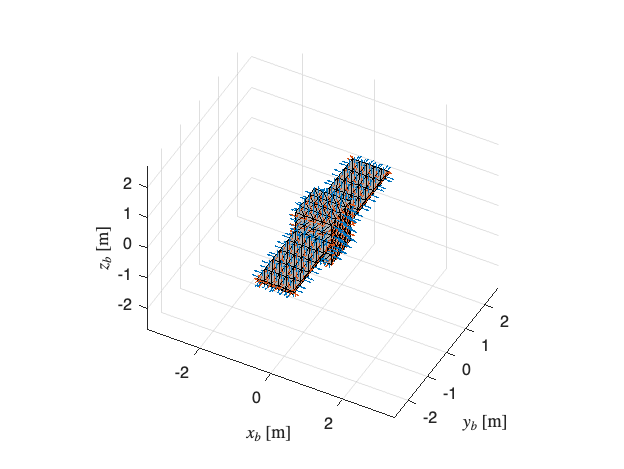

% train data ------
inputDim = 14; % [q, satPos, obsPos, sunPos, mApp_pastMean]
outputDim = 1; % [mApp]
x_train = trainDF(:,2:end);
y_train = trainDF(:, 1);

y_train(isinf(y_train)) = NaN;
y_train = fillmissing(y_train, 'previous'); % mAppのinfを直前の値に置換

% train data の各スカラー出力の平均を0にする for GPR
y_train_mean = mean(y_train); % [1, 1]
y_train = y_train - y_train_mean; % [:, 1], broadcasting

% valid data
t_ = valid.t_;
sat = valid.sat;
showSC(sat, "Normal", "on") % visualize satellite

### create a GP model (x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do) as a .mat file

tStartLearning = tic;
% [K_Dp, Kinv_Dp] = kernelMatrix(x_train, params); % x_train = [mApp, q, w]
K_Dp = 0; Kinv_Dp = 0; % 時間短縮のために一旦0で．．
[K_Do, Kinv_Do] = kernelMatrix(x_train(:,1:inputDim), params); % 
tEndLearning = toc(tStartLearning) / 60;
strcat("calculation time for learning [min] : ", num2str(tEndLearning))

ans = "calculation time for learning [min] : 11.6204"

fName = 'constGP';
save(strcat(fName, '.mat'), 'x_train', 'y_train', 'y_train_mean', 'K_Dp', 'Kinv_Dp', 'K_Do', 'Kinv_Do', 'params', '-v7.3');

## 逐次的に回帰を行い，回帰モデルの精度を確認

### conditions for ode

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

% 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); 

satPosIni = valid.satPos(1,:);
obsPosIni = valid.obsPos(1,:);
sunPosIni = valid.sunPos(1,:);
mApp_pastMeanIni = valid.mApp(1,1);

qIni = valid.q(1,:);
wIni = valid.w(1,:);

xIni = [qIni, wIni];

### ode と gpr を回して逐次的に回帰

% preallocation
x_reg = zeros(size(t_, 1), inputDim); % preallocation [q, satPos, obsPos, sunPos]. inputs for regression
x_reg(1,:) = [qIni, satPosIni, obsPosIni, sunPosIni, mApp_pastMeanIni]; % 初期値は真値
% x_reg(1,:) = qIni;

x_ode = zeros(size(t_, 1), size(xIni, 2));
x_ode(1,:) = xIni;

y_reg_mu = zeros(size(t_,1), outputDim); % [mApp]
y_reg_var = zeros(size(y_reg_mu));
y_reg = zeros(size(y_reg_mu));

for i = 1:1:size(t_, 1)-1

- gpr (observation step)

    [y_reg_mu(i,1), y_reg_var(i,1)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
    y_reg_mu(i,1) = y_reg_mu(i,1) + y_train_mean(1,1);
    y_reg(i,1) = y_reg_mu(i,1);

- predictionStep == 1. input: x_ode, output: x (1 step 後のodeに必要なx)

    if predictionStep == 1

        [t, x] = ode45(@(t, x)eomAtti_h(t, x, sat), tstep_span, x_ode(i,:), options);
        x_ode(i+1,:) = x(end,:);
        x_reg(i+1,1:4) = x_ode(i+1,1:4); % [q]
        x_reg(i+1,5:13) = x_reg(i,5:13); % [satPos, obsPos, sunPos]

        x_reg(i+1, 14) = (x_reg(i, 14) * tSpanPast + valid.mApp(i+1,1)) / (tSpanPast + 1); % [mApp_pastMean], 観測値を使う．

- predictionStep == 2. input: x_reg(i, :), output: y_reg_mu(i, 2:end)

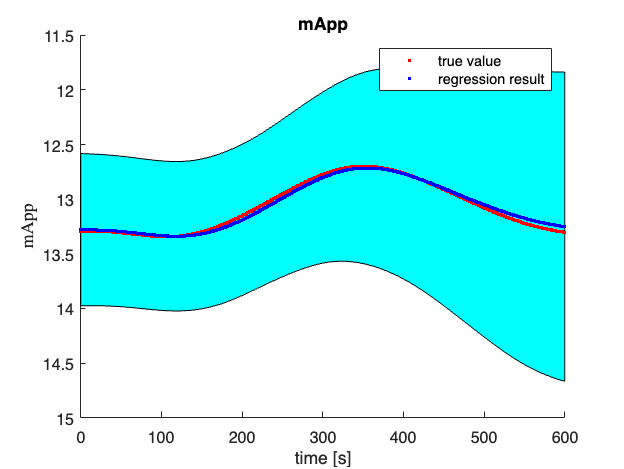

    elseif predictionStep == 2
        for j = 2:1:size(y_reg_mu, 2)

            [y_reg_mu(i+1,j), y_reg_var(i+1,j)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train(:,j), params, Kinv_Dp); % input: 
        end
        y_reg_mu(i,2:end) = y_reg_mu(i,2:end) + y_train_mean(i,2:end);
        y_reg(i+1,2:5) = qMult_h(y_reg(i,2:5), rv2q(y_reg_mu(i,2:4)));
        y_reg(i+1,6:end) = y_reg(i,6:end) + y_reg_mu(i,5:end);
    end
end

- 最後にもう一回 observation step

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(x_reg(end, :), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
y_reg_mu(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); 
y_reg(end,1) = y_reg_mu(end,1);

### export to csv

とりあえずしない

### plot

mkdir ../results/GP_static/
savedir = strcat(curdir, '/../results/GP_static/');

fignames = ["mApp"];
x_label = "time [s]";
y_labels = ["mApp"];

figure('Name', fignames(1));
plot_gpr(t_, y_reg(:,1), valid.mApp, y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);